clf;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
%low pass / high pass
tf1 = tf([1],[1,1]);
tf2 = tf([1,0],[1,1]);

%low pass / high pass
tf1 = tf([1,1],[1])

tf1 =
 
  s + 1
 
Continuous-time transfer function.



tf2 = tf([1,1],[1,0])

tf2 =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



plot weights

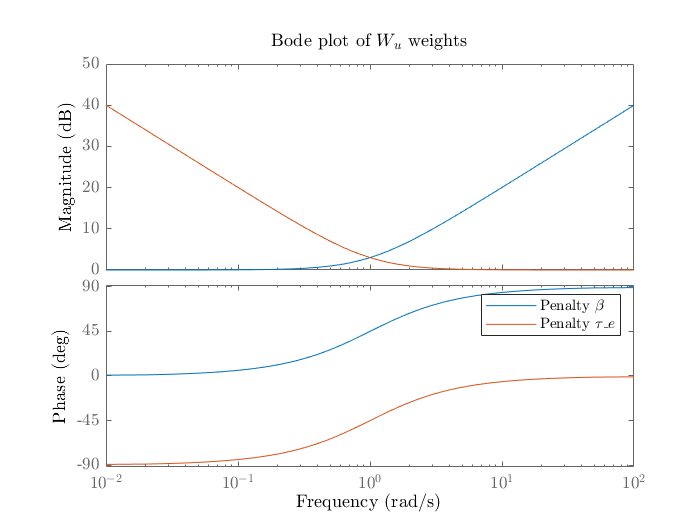

bode(tf1)
hold on
bode(tf2)
legend("Penalty $\beta$", "Penalty ${\tau}_{e}$")
xlabel('Frequency','interpreter', 'latex')
ylabel('Phase','interpreter', 'latex')
title('Bode plot of $W_u$ weights','interpreter', 'latex')
saveas(gcf, 'Figures/ch3_mimo_weights_filter.eps',  'epsc')

execute H_inf synthesis

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1,1:2));

Wp = 1;
Wu = [tf1 0; 0 tf2];
P11=[Wp; zeros(size(Wu,2),size(Wp,1))]; P12=[Wp*(G); Wu]; P21=eye(size(Wp)); P22=tf(G);
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 1, 1); %2 inputs, 2 outputs

Error using DynamicSystem/hinfsyn (line 130)
Plant P must have an explicit state-space realization.